# Lab 4

clear;
warning("off");

## Experiment 1

Ut = 0.025;
load("Ex_1_1.mat")



voltage1 = Diode_Voltage;
current1 = ch1;
[Is1, VT1, k1] = ekvfit(voltage1, current1, 0.005)

Is1 = 4.4707e-06

VT1 = 0.2404

k1 = 0.6333



load("Ex_1_2.mat")



voltage2 = Diode_Voltage;
current2 = ch1;
[Is2, VT2, k2] = ekvfit(voltage2, current2, 0.0005)

Is2 = 2.0185e-06

VT2 = 0.5356

k2 = 0.7402


load("Ex_1_3.mat")

voltage3 = Diode_Voltage;
current3 = ch1;
[Is3, VT3, k3] = ekvfit(voltage3, current3, 0.0005)

Is3 = 1.7781e-06

VT3 = 0.5720

k3 = 0.6999

load("Ex_1_4.mat")

voltage4 = Diode_Voltage;
current4 = ch1;
[Is4, VT4, k4] = ekvfit(voltage3, current3, 0.0005)

Is4 = 1.7781e-06

VT4 = 0.5720

k4 = 0.6999

figure(1)

[Is, VT, k] = ekvfit(voltage3, current3, 0.0005)

Is = 1.7781e-06

VT = 0.5720

k = 0.6999

compute_current = @(voltage) Is .* log(1 + exp((k*(voltage-VT))/(2*Ut))).^2;
theoretical_current1 = compute_current(voltage3)

theoretical_current1 =     0.0011    0.0010    0.0008    0.0007    0.0007    0.0006    0.0005    0.0005    0.0004    0.0004    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


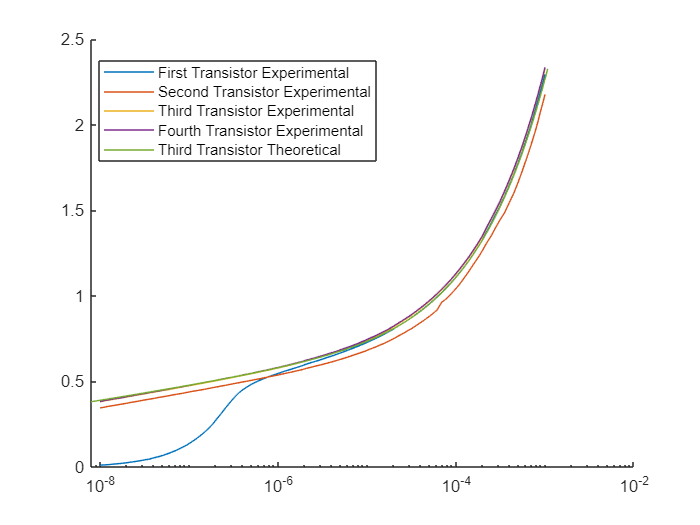

hold on 
plot(current1,voltage1, 'DisplayName',"First Transistor Experimental")
plot(current2,voltage2, 'DisplayName',"Second Transistor Experimental")
plot(current3,voltage3, 'DisplayName',"Third Transistor Experimental")
plot(current4,voltage4, 'DisplayName',"Fourth Transistor Experimental")
plot(theoretical_current1, voltage3, 'DisplayName',"Third Transistor Theoretical")
set(gca, "XScale", "log");
legend('show', 'Location', 'best');
hold off

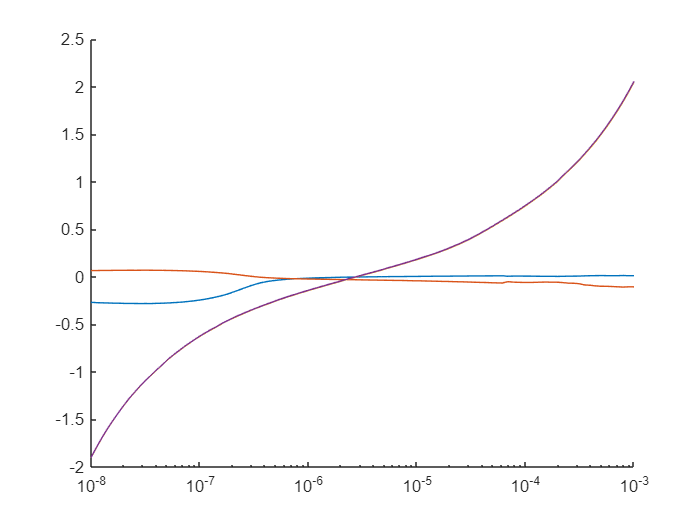

mean = (voltage1 + voltage2 + flip(voltage3) + flip(voltage4))/4;

clf;
figure(2)
hold on

plot(current1, voltage1 - mean)
plot(current2, voltage2 - mean)
plot(current3, voltage3 - mean)
plot(current4, voltage4 - mean)
set(gca, "XScale", "log");
hold off

## Experiment 2

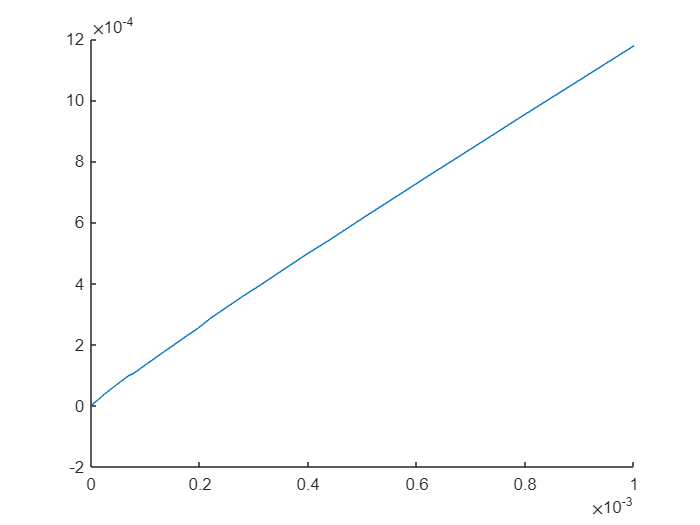

clear;
clf;
load("Ex_2_1.mat");
figure(3);
hold on
loglog(ch1, MDiode_Current);
hold off

## Experiment 3

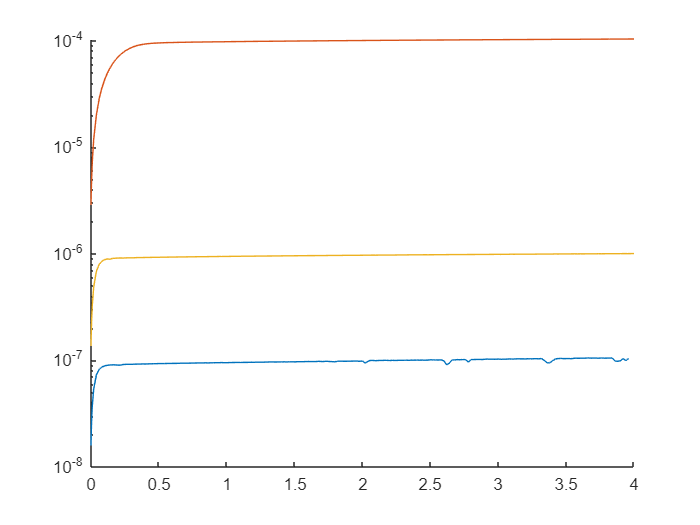

clear;
clf;
load("Ex_3_100nano.mat");
nano_100_voltage = ch2_voltage;
nano_100_current = mos_current;
load("Ex_3_1micro.mat");
micro_1_voltage = ch2_voltage;
micro_1_current = mos_current;
load("Ex_3_100micro.mat")
micro_100_voltage = ch2_voltage;
micro_100_current = mos_current;

figure();
hold on
plot(nano_100_voltage, nano_100_current);
plot(micro_100_voltage, micro_100_current);
plot(micro_1_voltage, micro_1_current);
set(gca, "YScale", "log");
xlim([0 4])
hold off